**INF6223**

**Devoir 1 - Partie I **

**Par : Pires LUFUNGULA & **

addpath('Résolution\fonctions')  % Ajout du chemin vers les fonctions au chemin de recherche MATLAB

**% Initialisation des chemins vers les fichiers audio**


fichierAudio1 = './Données_Audio/Données/gazouiller.wav'

fichierAudio1 = './Données_Audio/Données/gazouiller.wav'

fichierAudio2 = './Données_Audio/Données/sonor.wav'

fichierAudio2 = './Données_Audio/Données/sonor.wav'

**Lire et écouter les fichiers .wav**

% lecture & audition du fichier fichierAudio1 "gazouiller.wav"
audioinfo(fichierAudio1) %% Affichage des informations

ans = struct with fields:
             Filename: 'D:\Cours\Uqo\Automne 2023\2023-3-INF6223-01 Systèmes de communications multimédias\DEVOIR 1\tp1_MatLab_2023-3-INF6223-01\Données_Audio\Données\gazouiller.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 8000
         TotalSamples: 13129
             Duration: 1.6411
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 8


 
[y,Fs] = audioread(fichierAudio1,'native');   

% Audition du fichier 
sound(double(y),Fs);  

% lecture & audition du fichier fichierAudio2 "sonor.wav"
audioinfo(fichierAudio2) %% Affichage des informations

ans = struct with fields:
             Filename: 'D:\Cours\Uqo\Automne 2023\2023-3-INF6223-01 Systèmes de communications multimédias\DEVOIR 1\tp1_MatLab_2023-3-INF6223-01\Données_Audio\Données\sonor.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 8192
         TotalSamples: 73113
             Duration: 8.9249
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 8



[y2,Fs2] = audioread(fichierAudio2,'native'); % la fréquence d'échantillonnage dans la variable Fs2.
sound(double(y2),Fs2);   % Audition du fichier


**R1/ La fréquence d’échantillonnage Fe**

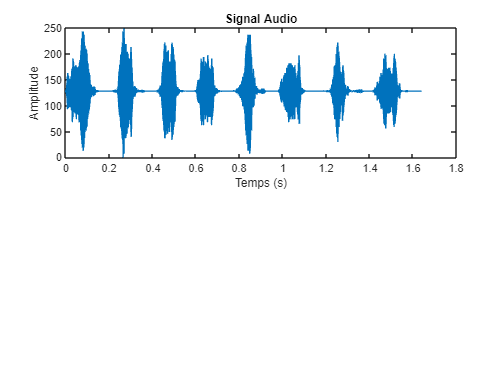

La fréquence d'échantillonnage (Fe) est : 8000 Hz


%Fe fichierAudio1 (gazouiller.wav)
figure;
afficher_info_audio(y,Fs)

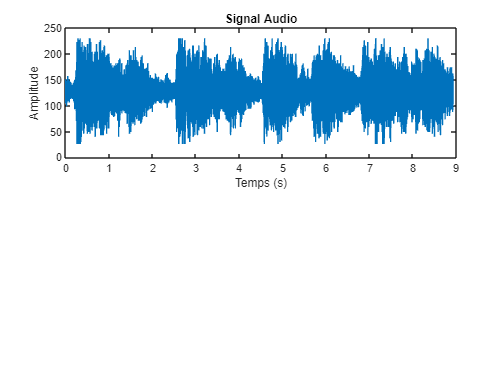

La fréquence d'échantillonnage (Fe) est : 8192 Hz



%Fe fichierAudio2 (sonor.wav)
figure;
afficher_info_audio(y2,Fs2)

**R2/  Le nombre de bits/sec du train de bits (bitstream) correspondant**

%Nbr de bits/sec pour fichierAudio1(gazouiller.wav)

debitBinaireAudio1 = calculer_debit_binaire(Fs)

debitBinaireAudio1 = 64000

disp(['Le débit binaire de fichierAudio1 (avec la résolution par 8 bit) est de ', num2str(debitBinaireAudio1), ' bits/sec.']); 

Le débit binaire de fichierAudio1 (avec la résolution par 8 bit) est de 64000 bits/sec.



%Nbr de bits/sec pour le fichierAudio2(sonor.wav)

debitBinaireAudio2 = calculer_debit_binaire(Fs2)

debitBinaireAudio2 = 65536

disp(['Le débit binaire de fichierAudio2 (avec la résolution par 8 bit) est de ', num2str(debitBinaireAudio2), ' bits/sec.']); 

Le débit binaire de fichierAudio2 (avec la résolution par 8 bit) est de 65536 bits/sec.


**R3/  L’amplitude minimale et maximale des échantillons audio**


fprintf('L’amplitude minimale et maximale des échantillons audio de deux fichiers\n');

L’amplitude minimale et maximale des échantillons audio de deux fichiers


calculer_amplitude_min_max(8)

L'amplitude minimale des échantillons audio pour une résolution de 8 bits est : -128
L'amplitude maximale des échantillons audio pour une résolution de 8 bits est : 127


**R4/  L’amplitude du 1000ième échantillon**

% Calcul de l'amplitude du 1000ième échantillon fichierAudio1(gazouiller.wav) 
amplitude_1000eme_echantillon_audio1 = double(y(1000)) - 128; 

% Afficher l'amplitude du 1000ième échantillon
disp('Amplitude du 1000ième échantillon audio1:');

Amplitude du 1000ième échantillon audio1:


disp(amplitude_1000eme_echantillon_audio1);

    -5




% Calcul de l'amplitude du 1000ième échantillon fichierAudio2(sonor.wav)
amplitude_1000eme_echantillon_audio2 = double(y2(1000)) - 128; 

% Afficher l'amplitude du 1000ième échantillon
disp('Amplitude du 1000ième échantillon audio2:');

Amplitude du 1000ième échantillon audio2:


disp(amplitude_1000eme_echantillon_audio2);

     8



**R5/  Représenter graphiquement, avec stem ( ) puis avec plot ( ), une portion de 100 échantillons de l’un des 2 signaux**** "fichierAudio1(gazouiller.wav)".**

% fichierAudio1(gazouiller.wav)
portion = y(1:100);

- Représentation avec stem()

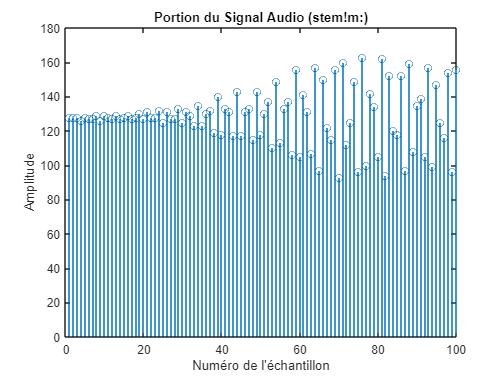

figure;
stem(1:100, portion);
title('Portion du Signal Audio (stem:)');
xlabel('Numéro de l''échantillon');
ylabel('Amplitude');

- Représentation avec plot()

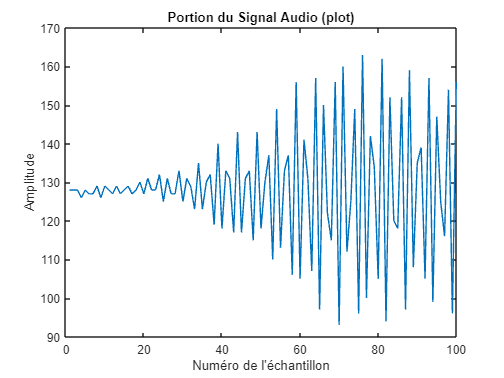

figure;
plot(1:100, portion);
title('Portion du Signal Audio (plot)');
xlabel('Numéro de l''échantillon');
ylabel('Amplitude');

Le choix des 100 premiers échantillons permet de fournir une portion représentative du début du signal audio. Cela donne une première impression de l’attrait général et des caractéristiques du signal au début. Ces 100 échantillons fournissent suffisamment de données pour visualiser sans surcharger le graphique. De plus, cette première partie du signal peut souvent fournir des informations extrêmement utiles sur les propriétés du signal audio, telles que le niveau moyen du signal, les transitions ou d'autres caractéristiques importantes.

La représentation visuelle de cette partie du signal audio est fournie par les figures **stem() et plot()**, qui montrent l'amplitude en fonction du numéro d'échantillon. Le premier utilise un graphique en **tiges** pour afficher chaque échantillon individuellement, tandis que le second utilise un graphique linéaire pour afficher **l'évolution de l'amplitude sur les échantillons**. Ces représentations permettent d'observer le comportement du signal audio dans cette partie initiale.

**R6/  Quel est l’effet de diminuer ou d’augmenter la fréquence d’échantillonnage lors de l’écoute ? **** "fichierAudio2(sonor.wav)".**

% Augmenter la fréquence d'échantillonnage

Fs_augmentee = 45100; %45,1 kHz
% Convertir le signal au format double
y2 = double(y2);

% Rééchantillonner le signal audio à la nouvelle fréquence
%Fs2 c'est la fe initial
y_augmentee = resample(y2, Fs_augmentee, Fs2);

% Jouer le signal rééchantillonné
sound(y_augmentee, Fs_augmentee);


% Diminuer la fréquence d'échantillonnage

Fs_diminuee = 2000; % 2 kHz

% Rééchantillonner le signal audio à la nouvelle fréquence
y_diminuee = resample(y2, Fs_diminuee, Fs2);

% Jouer le signal rééchantillonné
sound(y_diminuee, Fs_diminuee);


La fréquence d'échantillonnage est un paramètre important pour la qualité d'une transmission audio. Alors qu’une diminution de la fréquence dégrade la qualité, une augmentation de la fréquence l’améliore. Afin d'équilibrer la qualité audio avec les contraintes de stockage ou de transmission, il est important de sélectionner la fréquence de codage appropriée en fonction des besoins spécifiques. De manière générale, une fréquence de codage plus élevée est préférable pour une meilleure qualité audio.

**R7/  Lire les deux fichiers donnés en utilisant les fonctions audioread() mais sans l’option ‘Native’. **

% Lire le fichier audio sans l'option 'Native'
[y, Fs] = audioread(fichierAudio1);
[y2, Fs2] = audioread(fichierAudio2);

sound(y,Fs)

pause(2)

sound(y2,Fs2)

Dans ce cas particulier, lorsqu'on utilise **`audioread()` avec l'option `'native'`**, **le son n'est pas audible**. Cette limitation provient du fait que le format brut des données audio n'est pas immédiatement interprétable par les fonctions courantes de lecture audio, telles que `sound()` ou `audioplayer()`. En revanche, lorsque les fichiers audio sont lus sans l'option 'native', les données subissent une conversion dans un format standard, ce qui facilite considérablement la lecture audio et permet d'entendre le son.

**R8/  Synthèse de signaux audio **

% Paramètre du signal

A = 4;          % Amplitude
F1 = 200;       % Fréquence de s1 en Hz
F2 = 3000;      % Fréquence de s2 en Hz
Fe = 10000;     % Fréquence d'échantillonnage en Hz
N = 15000;      % Nombre d'échantillons

% Génération des échantillons de s1(n) et s2(n)
n= 0:N-1 ; % Indice des échantillons

s1 = A * cos(2 * pi * (F1 / Fe) * n);
s2 = A * cos(2 * pi * (F2 / Fe) * n);

% Calcul des fréquences f1 et f2
f1 = F1 / Fe;
f2 = F2 / Fe;

% Affichage des fréquences numériques
disp(['Fréquence numérique f1: ', num2str(f1)]);

Fréquence numérique f1: 0.02


disp(['Fréquence numérique f2: ', num2str(f2)]);

Fréquence numérique f2: 0.3


Representation graphique 

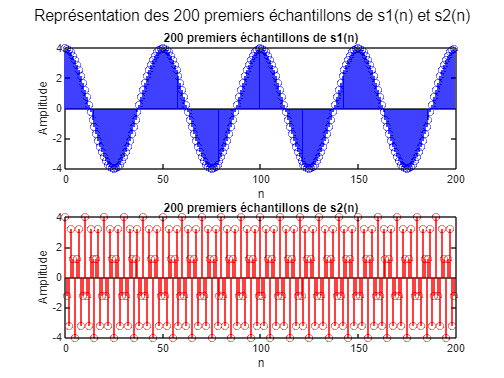

% Nombre d'échantillons à représenter
nb_echantillons = 200;

% Afficher les 200 premiers échantillons de s1(n)
figure;
subplot(2, 1, 1);
stem(n(1:nb_echantillons), s1(1:nb_echantillons), 'b');
title('200 premiers échantillons de s1(n)');
xlabel('n');
ylabel('Amplitude');


% Afficher les 200 premiers échantillons de s2(n)
subplot(2, 1, 2);
stem(n(1:nb_echantillons), s2(1:nb_echantillons), 'r');
title('200 premiers échantillons de s2(n)');
xlabel('n');
ylabel('Amplitude');



sgtitle('Représentation des 200 premiers échantillons de s1(n) et s2(n)');

En comparant les graphiques de fréquence des 200 premiers échantillons de s1(n) et s2(n), nous pouvons voir que s1(n) a une fréquence plus basse (200 Hz) que s2(n) (3000 Hz). Ceci est conforme à nos spécifications initiales, qui prévoyaient que F1 soit à 200 Hz et F2 à 3 000 Hz. Les sinusoïdes S1(n) et S2(n) ont des amplitudes identiques (A = 4).

**R9/  - Écouter (jouer) les deux signaux audio générés en 8** 

% Jouer le premier signal s1(n) 
sound(s1, Fe);

pause(3);

% Jouer le premier signal s2(n) 
sound(s2, Fe);

La principale distinction audible réside dans la tonalité des signaux. Le signal s1(n), du fait de sa fréquence plus basse, est perçu comme un son grave, tandis que le signal s2(n), avec une fréquence plus élevée, est perçu comme un son aigu. Cette perception de la tonalité est directement corrélée à la fréquence du signal audio.